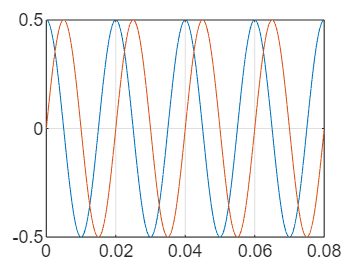

clear all
close all
clc
beep off


ts = 1e-4;
T = 20e-3;
time = [0:ts:4*T];
N = length(time);
theta = 2*pi/T*time;
ualpha = 0.5*cos(theta);
ubeta = 0.5*sin(theta);
figure; 
plot(time, ualpha, time, ubeta);
grid on


ua = zeros(1,N);
ub = zeros(1,N);
uc = zeros(1,N);
t0 = zeros(1,N);
t1 = zeros(1,N);
t2 = zeros(1,N);
up = ones(1,N)*sqrt(3)/2;
% for i=1:N
% ua(i) = ualpha(i);
% ub(i) = (-1/2*ualpha(i) + sqrt(3)/2*ubeta(i));
% uc(i) = (-1/2*ualpha(i) - sqrt(3)/2*ubeta(i));
% end
% figure; 
% plot(time, ua, time, ub, time, uc);
% grid on


#### sector constraints

for i=1:N

sector1 : ualpha >= 0; & ubeta >= 0; & ubeta <= sqrt(3) ualpha

    if ((ualpha(i) >= 0) && (ubeta(i) >= 0) && (ubeta(i) <= sqrt(3)*ualpha(i)))
                t2(i) = ubeta(i)*2/sqrt(3);
                t1(i) = ualpha(i) - ubeta(i)/sqrt(3);
                t0(i) = up(i) - t2(i) - t1(i);
                ua(i) = t0(i)/2;
                ub(i) = t1(i) + ua(i);
                uc(i) = t2(i) + ub(i);
    end

sector2 : ubeta >= 0; & ubeta >= sqrt(3) ualpha

    if ((ubeta(i) >= 0) && (ubeta(i) >= sqrt(3)*(ualpha(i))))
            t1(i) = -ualpha(i) + ubeta(i)/sqrt(3);
            t2(i) = (ualpha(i) - t1(i))*0.5 + ubeta(i)*sqrt(3)/2;
            t0(i) = up(i) - t2(i) - t1(i);
            ub(i) = t0(i)/2;
            ua(i) = t1(i) + ub(i);
            uc(i) = t2(i) + ua(i);
    end

sector3 : ualpha < 0; & ubeta >= 0; & ubeta < sqrt(3) ualpha

    if ((ualpha(i) < 0) && (ubeta(i) >= 0) && (ubeta(i) <= sqrt(3)*ualpha(i)))
                t2(i) = -ubeta(i)/sqrt(3) - ualpha(i);
                t1(i) = ubeta(i)*sqrt(3)/2 - (ualpha(i) + t2(i))*0.5;
                t0(i) = up(i) - t2(i) - t1(i);
                ub(i) = t0(i)/2;
                uc(i) = t1(i) + ub(i);
                ua(i) = t2(i) + uc(i);
    end

sector4 : ualpha < 0; & ubeta >= -sqrt(3) ualpha

    % section 4
    if ((ualpha(i) < 0) &&(ubeta(i) >= -sqrt(3)*ualpha(i)))
                t1(i) = -2/sqrt(3)*ubeta(i);
                t2(i) = ubeta(i)/sqrt(3) - ualpha(i);
                t0(i) = up(i) - t2(i) - t1(i);
                uc(i) = t0(i)/2;
                ub(i) = t1(i) + uc(i);
                ua(i) = t2(i) + ub(i);
    end

sector5 : ubeta < 0; & ubeta < -sqrt(3) ualpha

    if ((ubeta(i) < 0) && (ubeta(i) < -sqrt(3)*(ualpha(i))))
            t2(i) = ualpha(i) - 1/sqrt(3)*ubeta(i);
            t1(i) = -(ualpha(i)+t2(i))*0.5 - sqrt(3)/2*ubeta(i);
            t0(i) = up(i) - t2(i) - t1(i);
            uc(i) = t0(i)/2;
            ua(i) = t1(i) + uc(i);
            ub(i) = t2(i) + ua(i);
    end

sector6 : ualpha >= 0; & ubeta < 0; & ubeta >= -sqrt(3)ualpha

    if ((ualpha(i) >= 0) && (ubeta(i) < 0) && (ubeta(i) >= -sqrt(3)*ualpha(i)))
                t1(i) = ualpha(i) + ubeta(i)/sqrt(3);
                t2(i) = (ualpha(i) - t1(i))*0.5 - ubeta(i)*sqrt(3)/2;
                t0(i) = up(i) - t2(i) - t1(i);
                ua(i) = t0(i)/2;
                uc(i) = t1(i) + ua(i);
                ub(i) = t2(i) + uc(i);
    end

end of sv

end

plot results

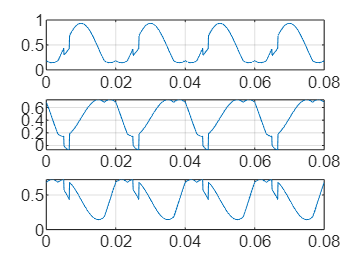

figure; 
subplot 311
plot(time, ua);
grid on
subplot 312
plot(time, ub);
grid on
subplot 313
plot(time, uc);
grid on